**Section 1:** get dimensions of image matrix.

color_img = imread('img.jpg');
display('our picture:')

our picture:


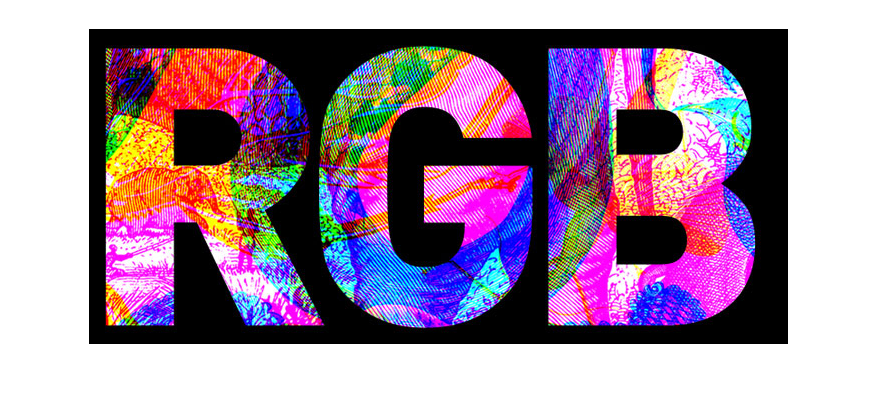

figure() 
imshow(color_img);

[r1,c1,numberofcolorchannels1] = size(color_img)

r1 = 315

c1 = 699

numberofcolorchannels1 = 3

dtype_color = class(color_img);
max_color = max(color_img(:))

max_color = uint8
255

min_color = min(color_img(:))

min_color = uint8
0

**section 2:** turning to colored image to a gray image.

gray = rgb2gray(color_img)

gray = 315×699 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

display('gray scale picture:')

gray scale picture:


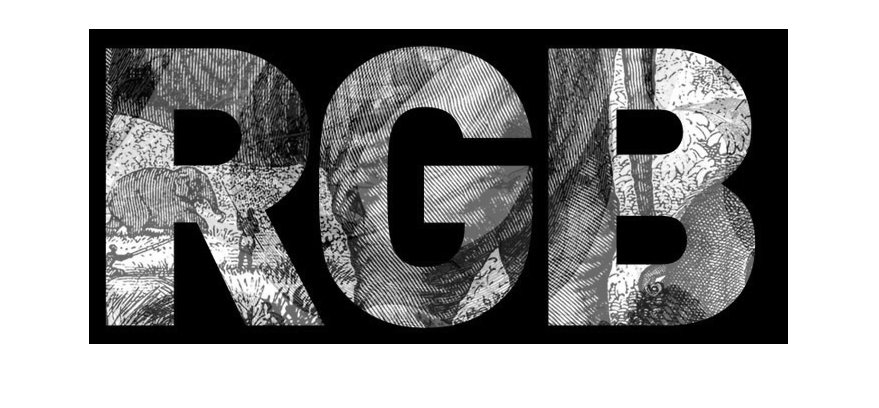

figure() 
imshow(gray);

**section 3: **max and min values for our gray-scale matrix

gray = rgb2gray(color_img);
max_gray = max(gray(:));
min_gray = min(gray(:));


**section 4: **turn colored picture to binary with loops.

n = numel(gray)

n = 220185

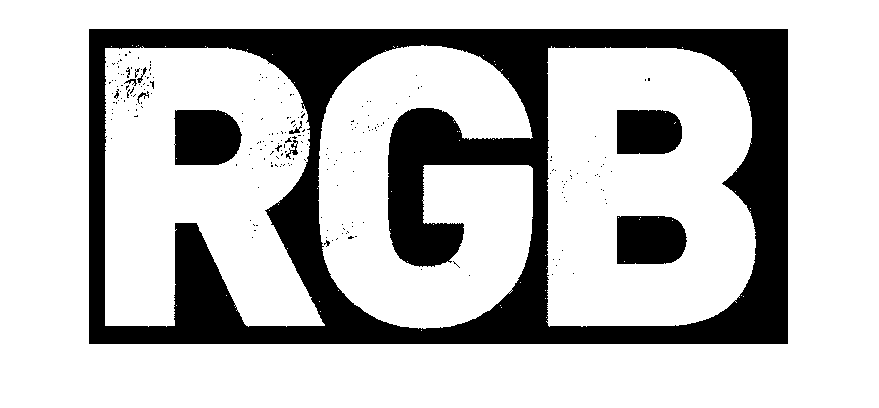

% n is the number of elements in the matrix gray
binary_picture = zeros(size(gray));
threshold = 10;
%for loop that goes from index 1 to n
for ii = 1:n
    if gray(ii) < 10
        binary_picture(ii) = 0;
    else
        binary_picture(ii) = 1;
    end
end
figure()
imshow(binary_picture,[0,1])

dtype_BW1 = class(binary_picture);
[rows2,columns2,numberofcolorchannels2] = size(binary_picture);

**section 6: **generating binary picture with a backround of top half black and buttom half grey. and plotting all the pictures together.

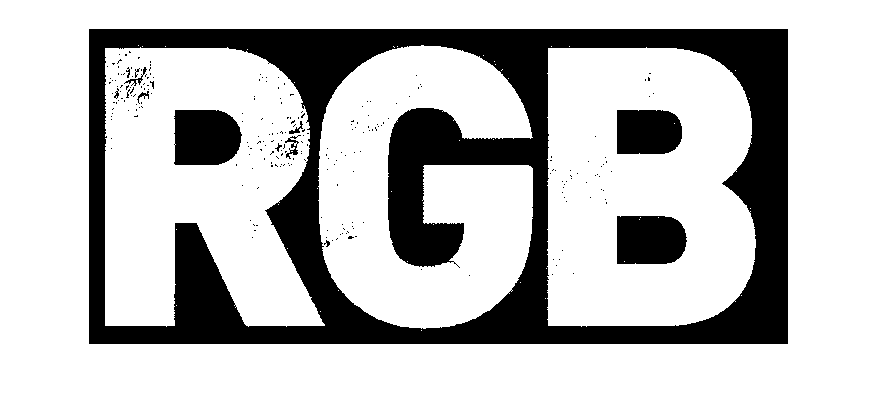

final_img = binary_picture*255;

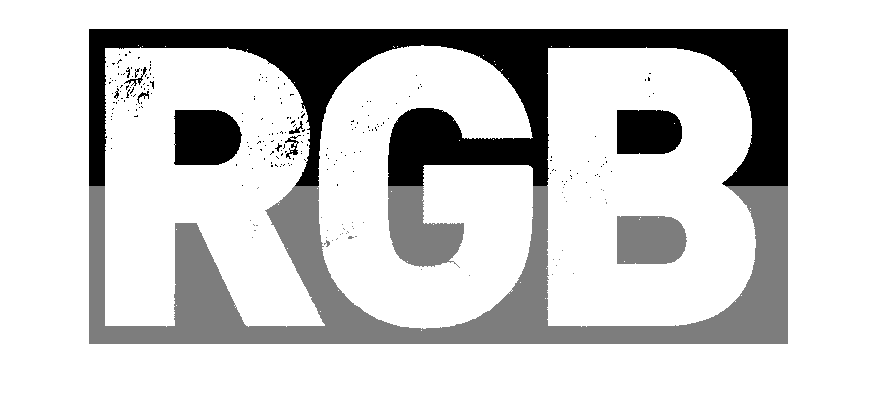

for var1 = round(r1/2):r1
    for var2 = 1:c1
        if binary_picture(var1,var2) == 0
            final_img(var1,var2) = 125;
        end
    end
end
figure()
imshow(final_img,[0,255])

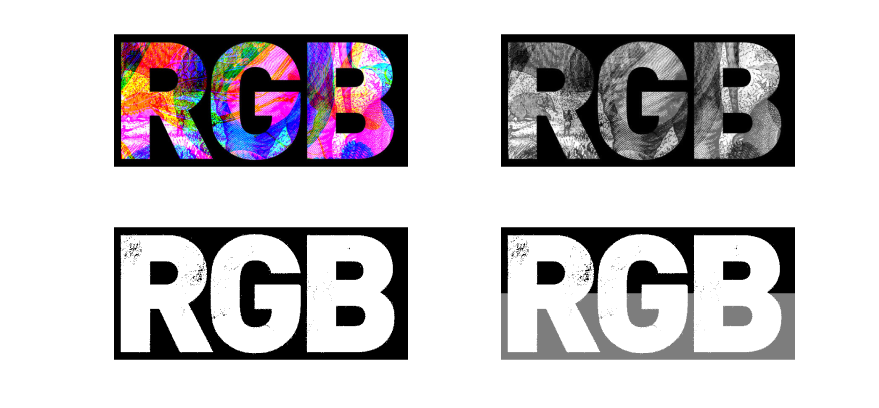




subplot(2,2,1) 
imshow(color_img)

subplot(2,2,2)
imshow(gray)

subplot(2,2,3)
imshow(binary_picture)

subplot(2,2,4)
imshow(final_img,[0,255])